UNTITLED Summary of this function goes here

Detailed explanation goes here

clear all
clc 
close all
% function [outputCloud] = pointCloudSeg()
inputCloud = pcread(['low_pitch_angle_slow_speed_right_turn1.pcd']);
filteredCloud = removeInvalidPoints(inputCloud);
filteredCloud.Count/1081

ans = 235.8973





%===================================

%======================================

%% plane 2 
% roi = [20,24;22,32;1,10];
% maxDistance = 5;
% referenceVector = [0,1,0];
% maxAngularDistance = 70;
%======================================

%% plane 3
% roi = [24,38; 23,inf;9.8,11.5];
% maxDistance = 1;
% referenceVector = [0,0,1];
% maxAngularDistance = 1;
%======================================


%% plane 4
% roi = [40.5,44;-3,9;1,inf];
% maxDistance = 3;
% referenceVector = [0,1,0];
% maxAngularDistance = 70;
%======================================


%% plane 5
% roi = [25,35; -16,20;5,6.3];
% maxDistance = 2;
% referenceVector = [0,0,1];
% maxAngularDistance = 1;
%======================================


%% plane 6
% roi = [23,24;-3,9.5;1,6];
% maxDistance = 5;
% referenceVector = [0,1,0];
% maxAngularDistance = 70;
%======================================

%% plane 7 
% roi = [-45.5,-34; -40,17.5;-5,-2];
% maxDistance = .4;
% referenceVector = [0,0,1];
% maxAngularDistance = 1;
%======================================

% %% plane 7 
% roi = [-10,0; -45,0;-4,-1.5];
% maxDistance = 2;
% referenceVector = [0,0,1];
% maxAngularDistance = 60;
% %======================================

%% plane 7 
% roi = [0,21; -40,40;-4,-0.5];
% maxDistance = 1;
% referenceVector = [0,0,1];
% maxAngularDistance = 30;
%======================================

%% plane 7 
roi = [-45,17; 20,40;-5,-2.5];
maxDistance = .6;
referenceVector = [0,0,1];
maxAngularDistance = 20;
%======================================

sampleIndices = findPointsInROI(filteredCloud,roi);
sIndicesSorted = sort(sampleIndices);
roi_cloud = select(filteredCloud,sIndicesSorted);
count_roi = roi_cloud.Count

count_roi = 6464

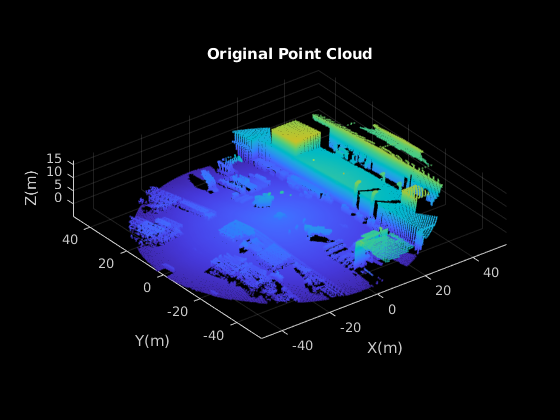

% pcwrite(roi_cloud,'roi_cloud1.pcd');


figure
pcshow(filteredCloud)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
title('Original Point Cloud')

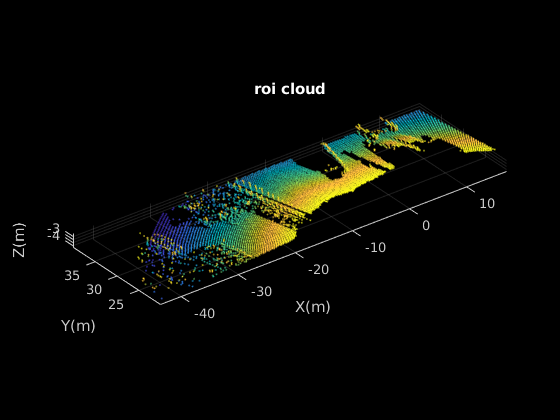



figure(2)
pcshow(roi_cloud)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
title('roi cloud')



[model1,inlierIndices,outlierIndices] = pcfitplane(roi_cloud,...
            maxDistance,referenceVector,maxAngularDistance);


iIndicesSorted = sort(inlierIndices);
wall_seg_cloud = select(roi_cloud,iIndicesSorted);
count_wall = wall_seg_cloud.Count

count_wall = 5575

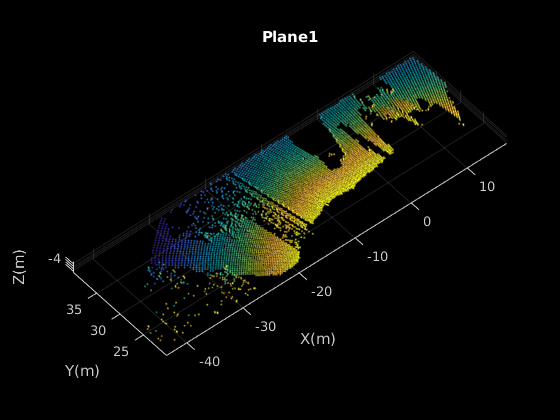



figure(3)
pcshow(wall_seg_cloud)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
title('Plane1')



remainPtCloud = select(roi_cloud,outlierIndices);
pcwrite(wall_seg_cloud,'wall_seg_cloud_n.pcd');
fileID = fopen('wall_seg_n.txt','w');
nbytes = fprintf(fileID, 'Sample Indices\n');
nbytes = fprintf(fileID, 'Indices Size:\n');
nbytes = fprintf(fileID, '%d\n',size(sIndicesSorted,1));
nbytes = fprintf(fileID, 'Data:\n');
nbytes = fprintf(fileID, '%d\n',sIndicesSorted);
nbytes = fprintf(fileID, 'Coefficient of the plane:\n');
nbytes = fprintf(fileID, '%f %f %f %f\n',model1.Parameters);
nbytes = fprintf(fileID, 'Inliers Indices\n');
nbytes = fprintf(fileID, 'Indices Size:\n');
nbytes = fprintf(fileID, '%d\n',size(inlierIndices,1));
nbytes = fprintf(fileID, 'Data:\n');
nbytes = fprintf(fileID, '%d\n',iIndicesSorted);


fileID = fopen('wall_seg_n.txt','r');
tline = fgetl(fileID)

tline = 'Sample Indices'

tline = fgetl(fileID)

tline = 'Indices Size:'

size1 = fgetl(fileID)

size1 = '6464'

tline = fgetl(fileID)

tline = 'Data:'

formatSpec = '%d';
index_roi = fscanf(fileID,formatSpec)

index_roi =        75534
       75891
       76244
       76245
       76246
       76247
       76248
       76599
       76600
       76601


tline = fgetl(fileID)

tline = 'Coefficient of the plane:'

tline = fgetl(fileID)

tline = '-0.022853 0.118932 0.992639 -0.761544'

tline = fgetl(fileID)

tline = 'Inliers Indices'

tline = fgetl(fileID)

tline = 'Indices Size:'

tline = fgetl(fileID)

tline = '5575'

tline = fgetl(fileID)

tline = 'Data:'

index_plane = fscanf(fileID,formatSpec)

index_plane =    230
   231
   260
   261
   262
   263
   264
   265
   266
   267


fclose(fileID);